clc
clear all;

beta_mat = 0.0:0.02:0.5;

% size_beta = size(beta_mat,2);
% 
% joint_value = zeros(size_beta,1);
% joint_avg= zeros(size_beta,1);
% joint_std= zeros(size_beta,1);
% 
% sum_value = zeros(size_beta,1);
% sum_avg = zeros(size_beta,1);
% sum_std = zeros(size_beta,1);
% 
% 
% for i = 1: size_beta
%     beta = beta_mat(i);
%     [joint_value(i),joint_avg(i),joint_std(i)] = joint_diff(beta);
%     [sum_value(i), sum_avg(i), sum_std(i)] = disjoint_diff(beta);
% end

% save('result_diff/result_joint','joint_value','joint_avg','joint_std')
% save('result_diff/result_disjoint','sum_value','sum_avg','sum_std')

% size_beta = size(beta_mat,2);
% 
% value_wind = zeros(size_beta,1);
% value_storage = zeros(size_beta,1);
% avg_wind = zeros(size_beta,1);
% avg_storage = zeros(size_beta,1);
% 
% for i = 1: size_beta
%     beta = beta_mat(i);
%     [value_wind(i),value_storage(i), avg_wind(i), avg_storage(i)] = Sep_disjoint_diff(beta);
% end

% save('result_diff/result_sep_disjoint','value_wind','value_storage','avg_wind',"avg_storage")


### 画图

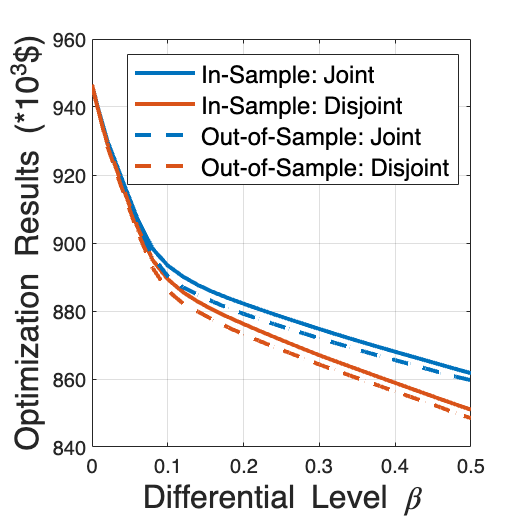


load('result_diff/result_disjoint.mat')
load('result_diff/result_joint.mat')
hFig = figure;
set(hFig, 'Position', [100 100 400 400]); % Square of 400x400 pixels

plot(beta_mat, joint_value,'LineStyle', '-', 'LineWidth', 2, 'Color', [0, 0.4470, 0.7410]);% Plot the line
hold on; 
plot(beta_mat, sum_value,'LineStyle', '-', 'LineWidth', 2, 'Color', [0.8500, 0.3250, 0.0980]);
hold on;
plot(beta_mat, joint_avg,'LineStyle', '--', 'LineWidth', 2, 'Color', [0, 0.4470, 0.7410]);
hold on; 
plot(beta_mat, sum_avg,'LineStyle', '--', 'LineWidth', 2, 'Color', [0.8500, 0.3250, 0.0980]);
hold off;

h_legend = legend('In-Sample: Joint', 'In-Sample: Disjoint', 'Out-of-Sample: Joint', 'Out-of-Sample: Disjoint');

% Label the axes and give the plot a title
h_xlabel = xlabel('Differential Level \beta');
h_ylabel = ylabel('Optimization Results (*10^3$)');

set(h_xlabel, 'FontSize', 16);
set(h_ylabel, 'FontSize', 16);
set(h_legend, 'FontSize', 12);

% Add grid lines to the plot for better readability
grid on;

saveas(hFig, 'result_diff/Two_settle_opt.pdf');

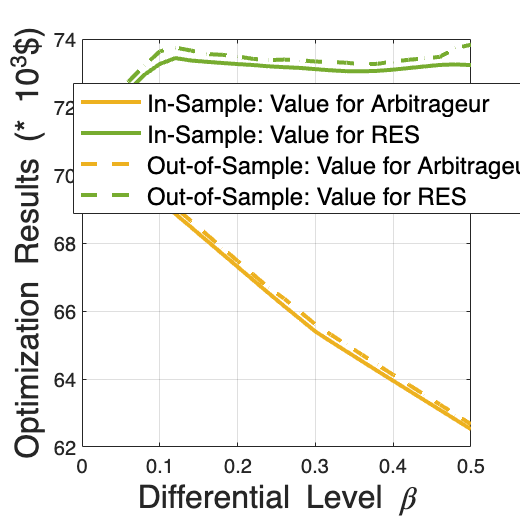

load('result_diff/result_sep_disjoint')
load('result_diff/result_joint.mat')

value_Arb = value_storage;
value_RES = joint_value - value_wind;

avg_Arb = avg_storage;
avg_RES = joint_avg - avg_wind;

hFig = figure;
set(hFig, 'Position', [100 100 400 400]); % Square of 400x400 pixels


plot(beta_mat, value_Arb,'LineStyle', '-', 'LineWidth', 2, 'Color', [0.9290, 0.6940, 0.1250]	);% Plot the line
hold on; 
plot(beta_mat, value_RES,'LineStyle', '-', 'LineWidth', 2, 'Color', [0.4660, 0.6740, 0.1880]);
hold on;
plot(beta_mat, avg_Arb,'LineStyle', '--', 'LineWidth', 2, 'Color', [0.9290, 0.6940, 0.1250]	);
hold on; 
plot(beta_mat, avg_RES,'LineStyle', '--', 'LineWidth', 2, 'Color', [0.4660, 0.6740, 0.1880]);
hold off;

h_legend = legend('In-Sample: Value for Arbitrageur', 'In-Sample: Value for RES', 'Out-of-Sample: Value for Arbitrageur', 'Out-of-Sample: Value for RES', 'Position', [0.32 0.64 0.55 0.15]);

% Label the axes and give the plot a title
h_xlabel = xlabel('Differential Level \beta');
h_ylabel = ylabel('Optimization Results (* 10^3$)');

set(h_xlabel, 'FontSize', 16);
set(h_ylabel, 'FontSize', 16);
set(h_legend, 'FontSize', 12);

% Add grid lines to the plot for better readability
grid on;

saveas(hFig, 'result_diff/Two_settle_value.pdf');